# Hands on - preprocessing with EEG data

## Contents

- Band-pass filtering

- Data segmentation

- Singular value decomposition (SVD) and principal component analysis (PCA)

- Independent component analysis (ICA)

Add external libraries

eeglab;

Some menu items hidden. Use Preference menu to show them all.
eeglab: options file is ~/eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "AAR" v131130 (see >> help eegplugin_aar)
EEGLAB: adding "AMICA" v1.7 (see >> help eegplugin_amica)
EEGLAB: adding "ANTeepimport" v1.14 (see >> help eegplugin_eepimport)
EEGLAB: adding "Adjust" v1.1.1 (see >> help eegplugin_adjust)
EEGLAB: adding "BDFimport" v1.2 (see >> help eegplugin_bdfimport)
EEGLAB: adding "Biosig" v3.8.4 to the path
EEGLAB: adding "EEG-BIDS" v9.1 (see >> help eegplugin_eegbids) - new version 10.1 available
EEGLAB: adding "ICLabel" v1.6 (see >> help eegplugin_iclabel)
EEGLAB: adding "MARA" v1.2 (see >> help eegplugin_MARA)
EEGLAB: adding "bva-io" v1.73 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.91 (see >> help eegplugin_clean_rawdata) - new version 2.10 available
EEGLAB: adding "dipfit" v5.4 (see >> help eegplugin_dipfit) - new version 5.5 available
EEG

ft_defaults;

-------------------------------------------------------------------------------------------
FieldTrip is developed by members and collaborators of the Donders Institute for Brain,
Cognition and Behaviour at Radboud University, Nijmegen, the Netherlands.

                          --------------------------
                        /                            \
                     ------------------------------------
                    /                                    \
          -------------------------------------------------
         /                            /\/\/\/\/\ 
         ---------------------------------------------------
                  |        F  i  e  l  d  T  r  i  p       |
                  ------------------------------------------
                   \                                      /
                     ------------------------------------
                          \            /
                            ----------

Please cite the FieldTrip re

add_paths_Won2021;

Parameters

ch = 1:32; % select channels

Params_P3speller = struct('freq', [1 40], 'frame', [0 1000], ...
    'baseline', [-200 0], 'select_ch', 1:32);
electrodes_midline = {'FZ', 'Cz', 'Pz'};
electrodes_eyes = {'FP1', 'FP2', 'AF3', 'AF4'};

### Load one participant data

There are many runs in either test or train, but we will only load a single run for this hands-on


for nsb=1 % :55
    fname_train = sprintf('../data/s%02d.mat', nsb);
    EEG = load(fname_train);
    eeg_test = EEG.test;
    
    eeg_nontarget = [];
    for nRun = length(eeg_test) % 1:length(eeg_test)
        cur_eeg = eeg_test{nRun};
    end
end

## Visual inspection

- Frequency domain: power spectral density (PSD)

- Time domain: scroll display

close all;

data_untouched = cur_eeg.data; % [ch x time]
srate = cur_eeg.srate; % sampling frequency 
ch_locs = cur_eeg.chanlocs; % channel location and label info.

% Display data in frequency comain
figure,
spectopo(data_untouched, 0, srate);

Computing spectra (window length 512; fft length: 512; overlap 0):
................................
Click on each trace for channel/component index


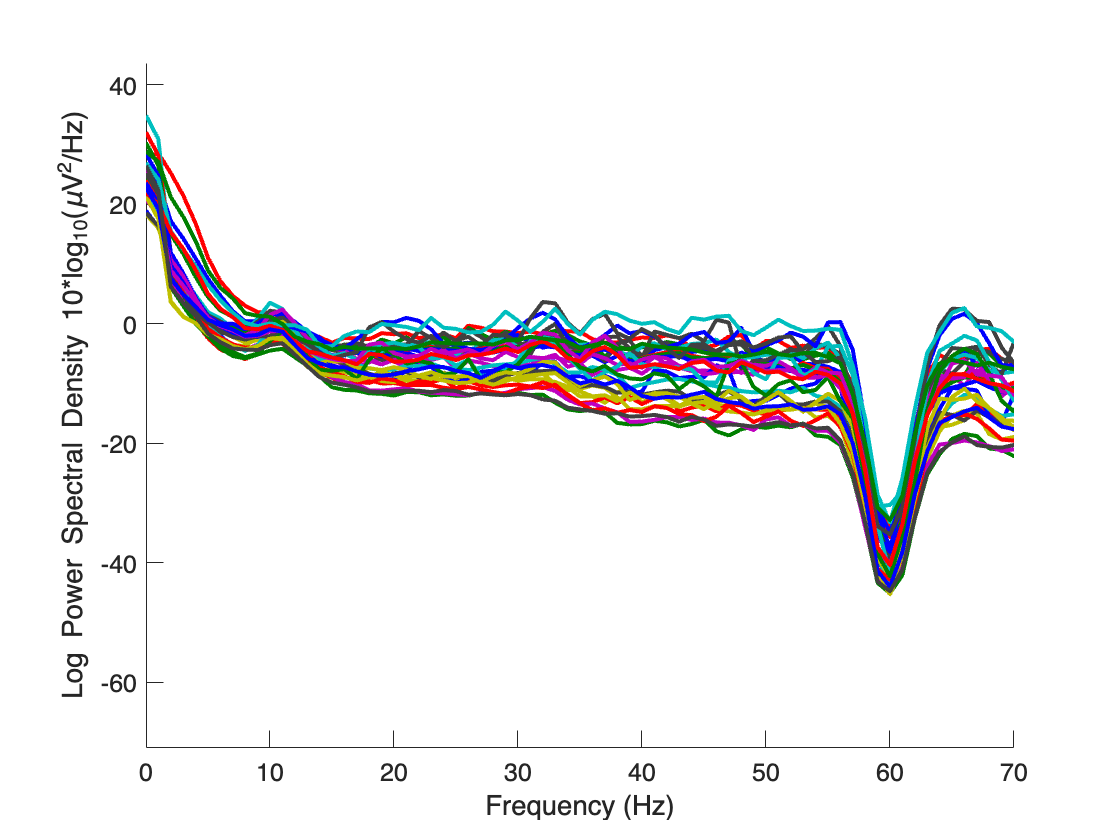

xlim([0, 70]);

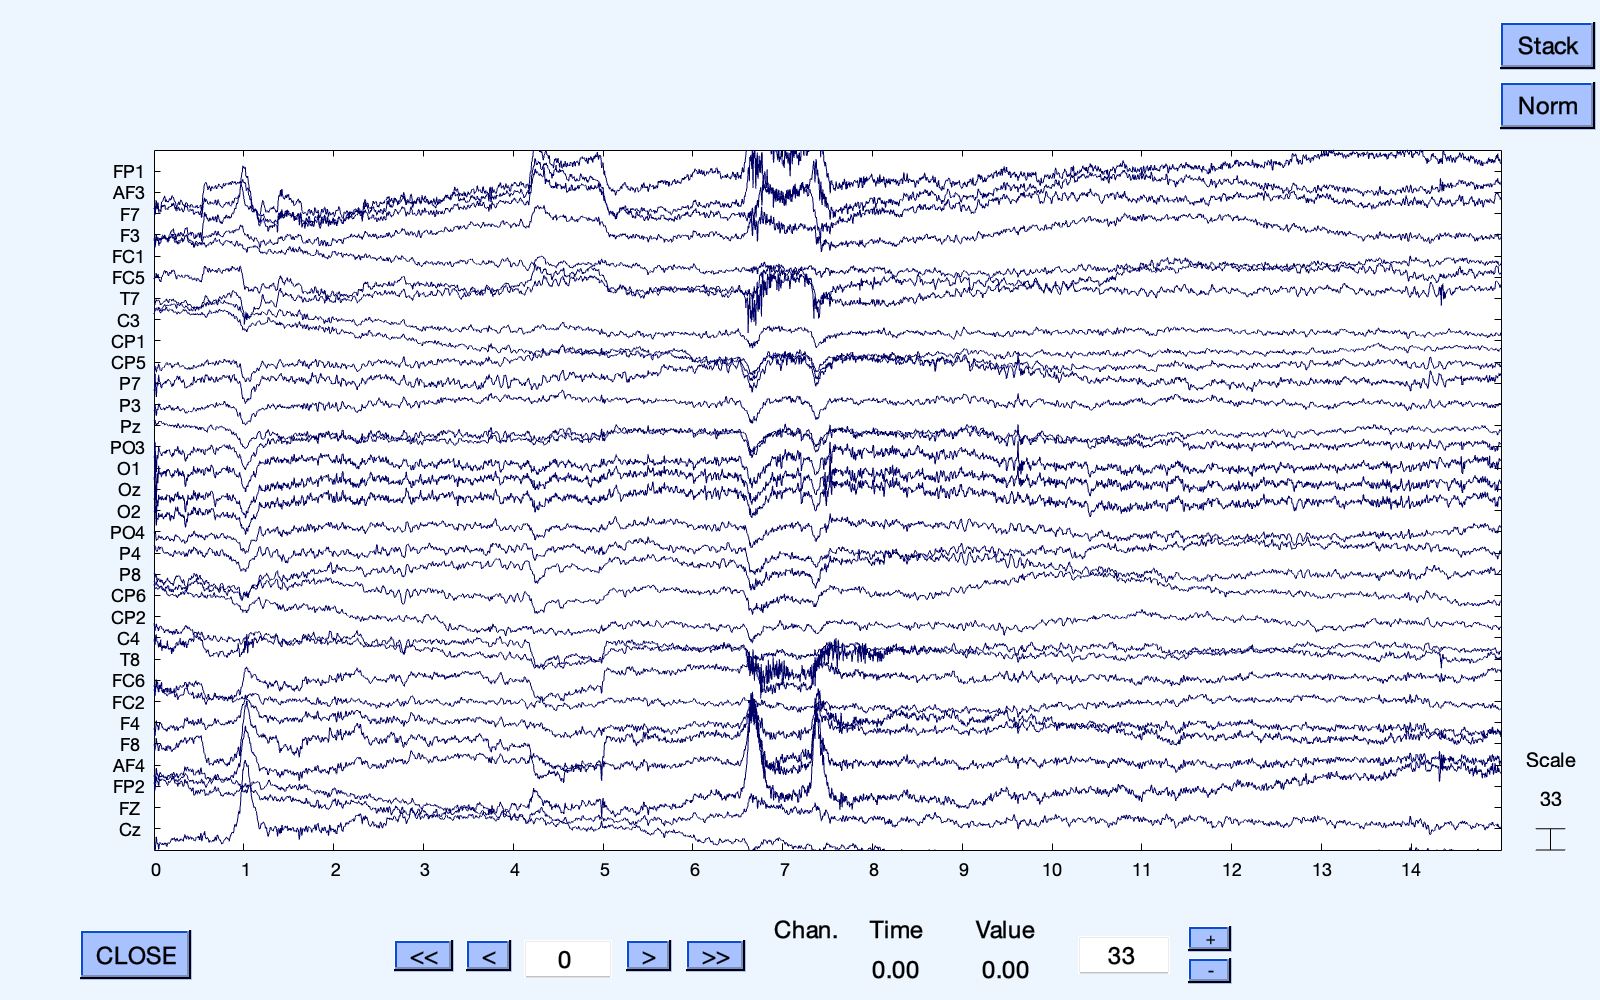

% Display data in time domain (scroll display)
eegplot(data_untouched, 'srate', srate, 'winlength', 15, 'eloc_file', ch_locs);

### Extract noisy period (huge amplitude fluctuation)

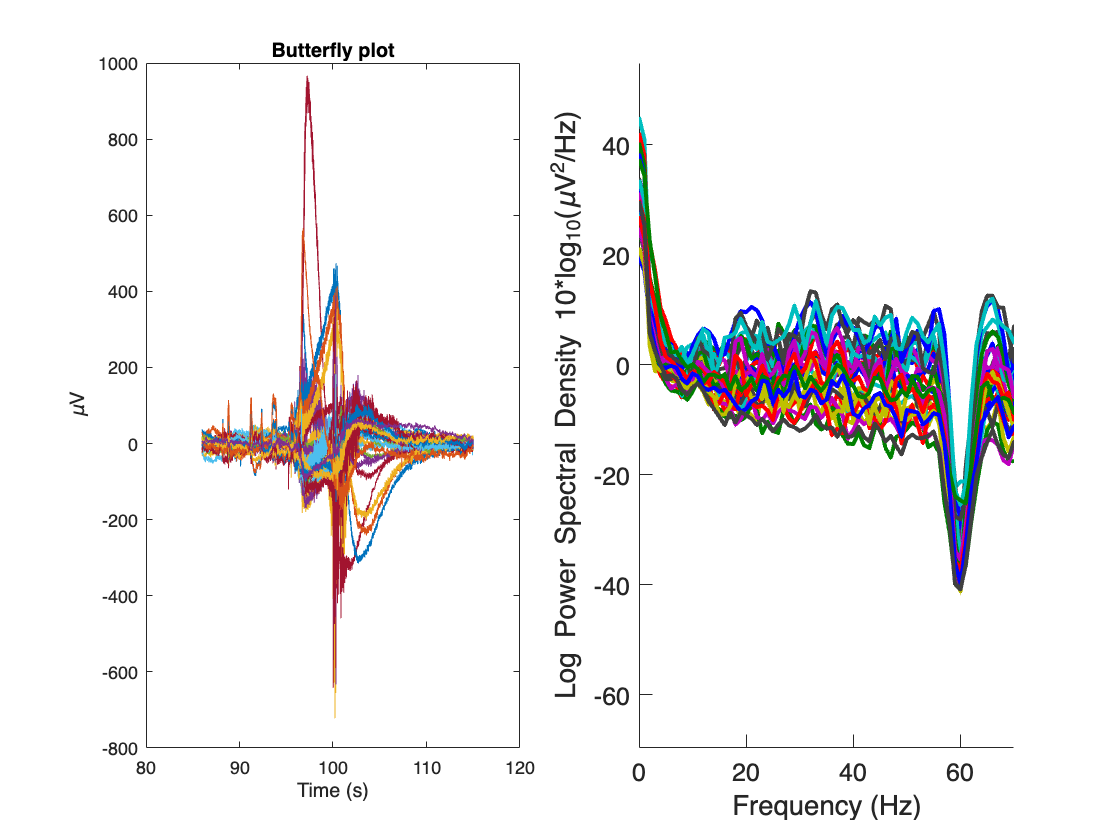

Computing spectra (window length 512; fft length: 512; overlap 0):
................................
Click on each trace for channel/component index


% We visually checked there is huge amplitude fluctuation around 80-100 s.

% Crop data containing the noise
data_nearby_artifacts = data_untouched(:, 86*srate:115*srate);
t = linspace(86, 115, size(data_nearby_artifacts, 2));

% Check in butterfly plot (all channels on the x-axis)
figure, 
subplot(1,2,1); plot(t, data_nearby_artifacts'); title('Butterfly plot');
xlabel('Time (s)'); ylabel('\muV'); 
subplot(1,2,2); spectopo(data_nearby_artifacts, 0, srate); xlim([0, 70]);

Now let's exclude huge amplitude noise manually, and check the influence on EEG data in time and frequency domain. However, it is not recommendable as we manully cropped data from continuous data. 

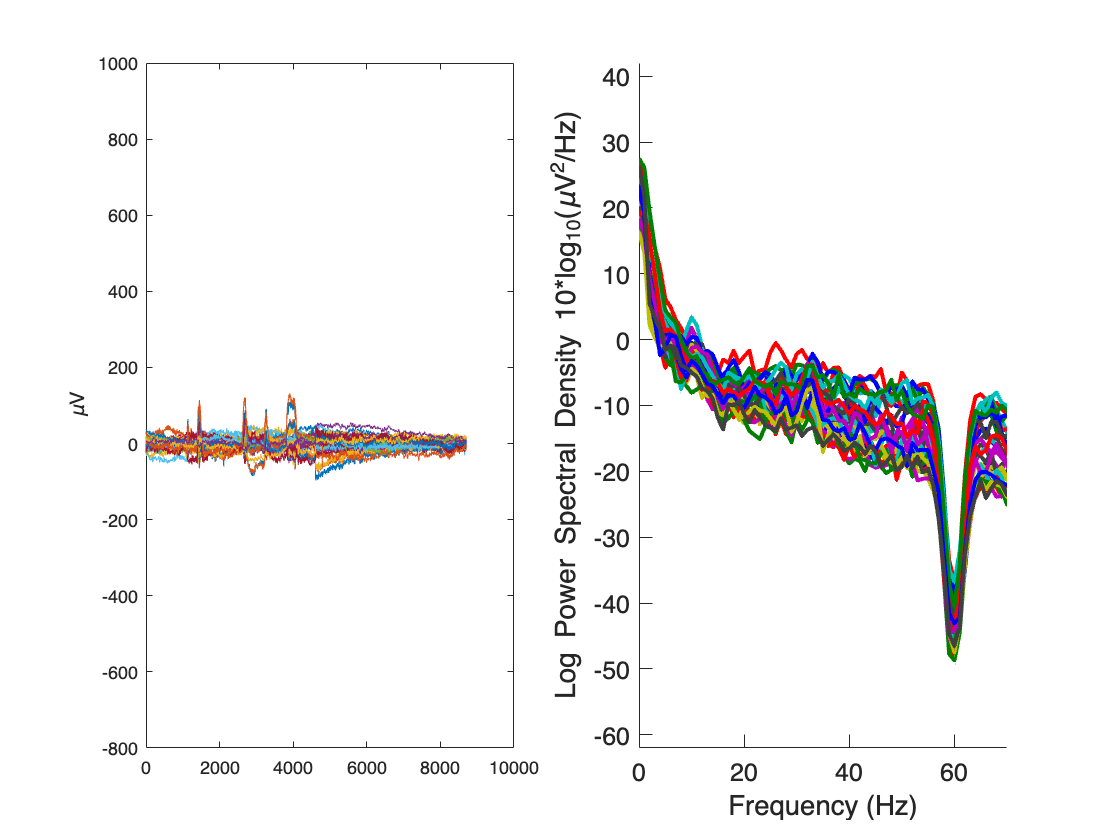

Computing spectra (window length 512; fft length: 512; overlap 0):
................................
Click on each trace for channel/component index


data_nearby_artifacts(:, 9*srate:21*srate) = []; % containing those artifacts

figure,
subplot(1,2,1); plot(data_nearby_artifacts'); ylim([-800, 1000]); % same ylim as above
ylabel('\muV');

subplot(1,2,2); spectopo(data_nearby_artifacts, 0, srate); ylim([-62, 42]); xlim([0, 70]);

You can see the difference!

## Phase shift caused by causal filtering

Causal filtering could make phase shift, meaning that filtered data have phase delay. It will affect your insights.

### Test with causal FIR lowpass filter

### Design Filter

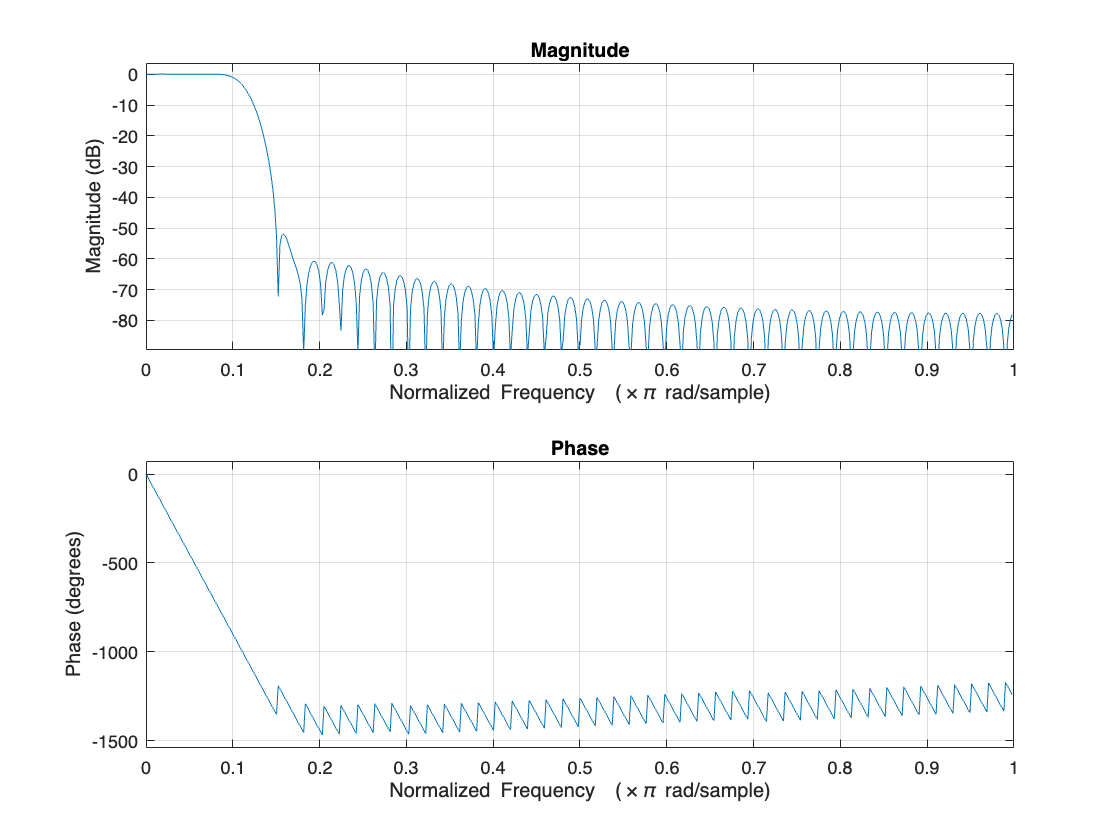

% Simple filter design
Fs = srate;
fc = 30; % cutoff frequency
order = 100;

b = fir1(order, fc/(Fs/2)); % FIR filter coefficients
figure,
freqz(b, 1, Fs); % filter property, s.t. frequency response

### Applying causal filter

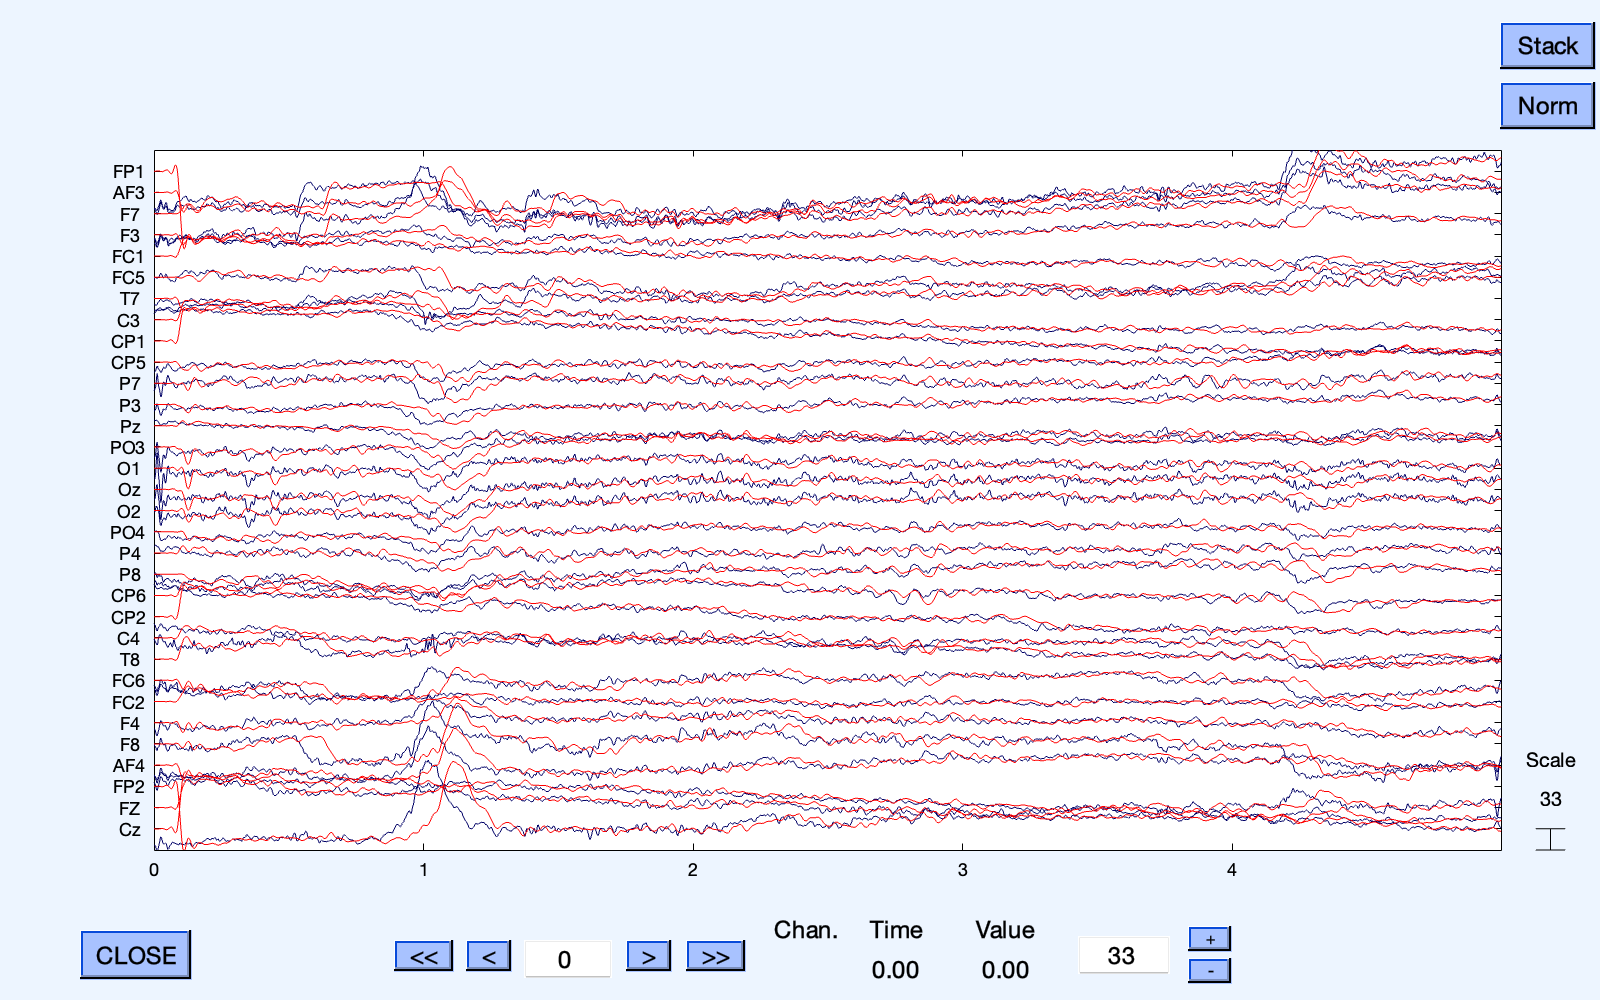

eeg_shifted = filter(b, 1, data_untouched');  % Apply causal filter
eegplot(data_untouched, 'data2', eeg_shifted', 'srate', cur_eeg.srate, 'eloc_file', cur_eeg.chanlocs);

Now you notice there is phase shift between blue and red lines, where blue lines indicate EEG before filtering and red lines indicate filtered data

### Applying zero-phase filter

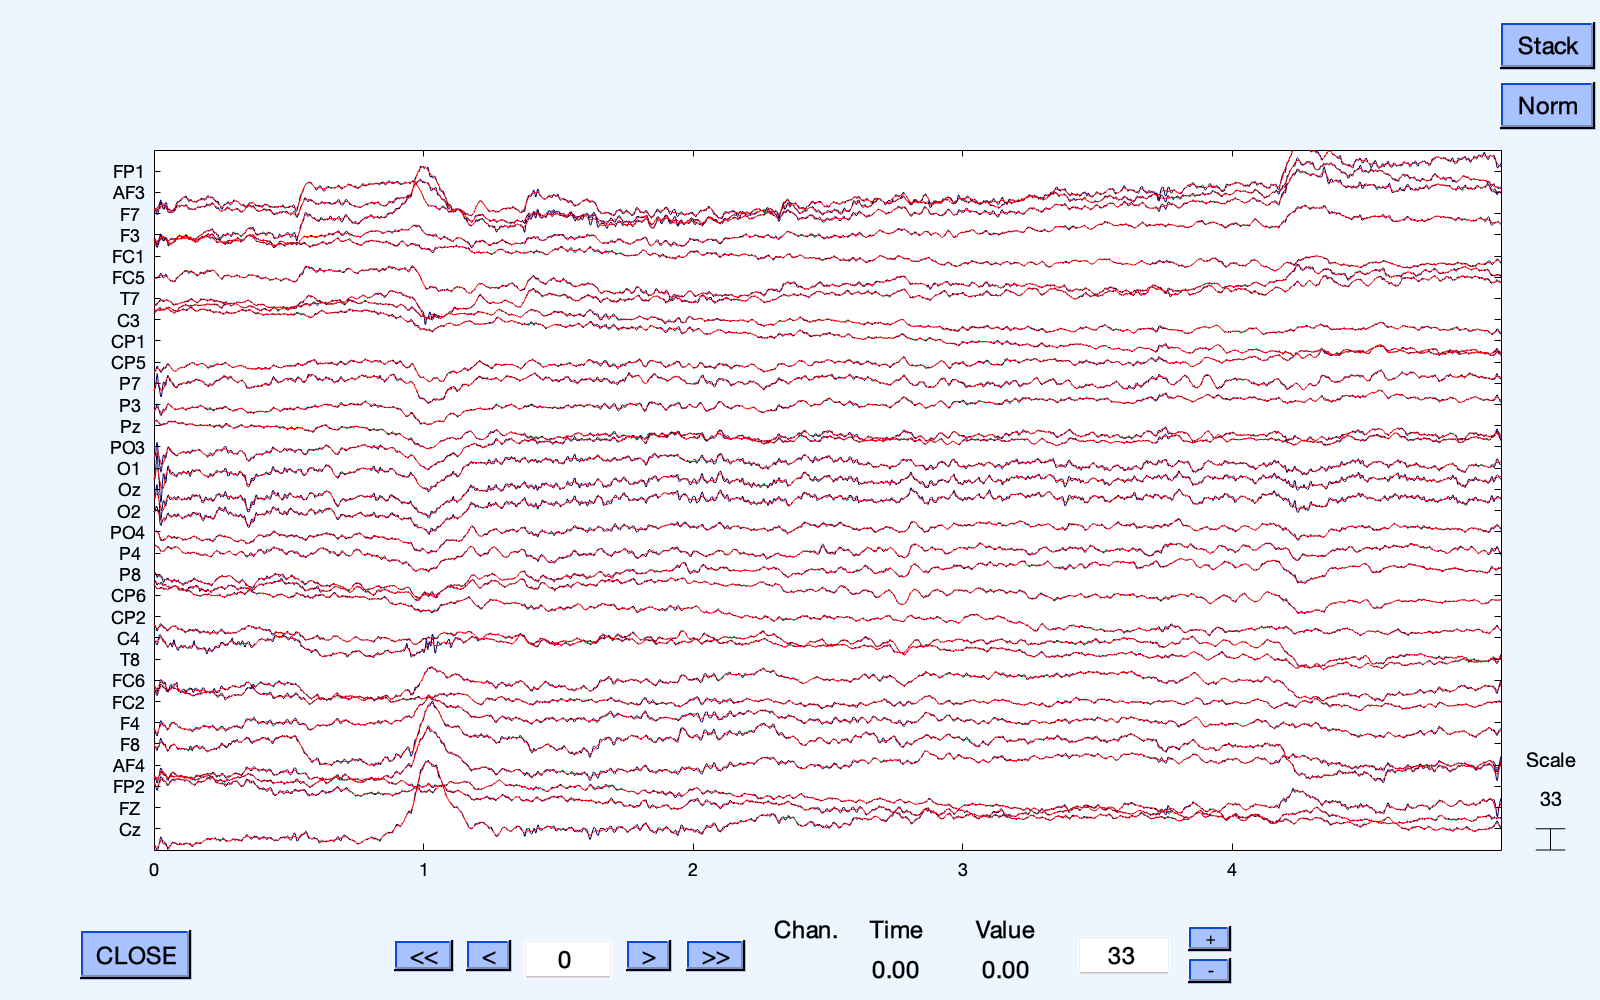

eeg_zero_phase_filtered = filtfilt(b, 1, data_untouched');  % Apply causal filter
eegplot(data_untouched, 'data2', eeg_zero_phase_filtered', ...
    'srate', cur_eeg.srate, 'eloc_file', cur_eeg.chanlocs);

By applying backward and foward filtering, you can avoid phase shift.

## Data segmentation

From continuous 2D data, you can get segmented (epoched) data using event markers, meaning that you can only have EEG data of interest, EEG data per class, etc.

In this dataset, we have event markers have either 0, 1, and 2, where 0 indicates no event, 1 indicates target events, and 2 indicates non-target events.

event_markers = cur_eeg.markers_target;
disp(unique(event_markers));

     0     1     2




% Extract target event markers
tmp_target = event_markers;
tmp_target(tmp_target==2) = 0; % remove non-target markers
% tmp_target: 1 for target o/w 0

% Extract non-target event markers
tmp_nontarget = event_markers;
tmp_nontarget(tmp_nontarget==1) = 0; % remove target merkers
tmp_nontarget = sign(tmp_nontarget);
% tmp_nontarget: 1 for nontarget o/w 0

Apply additional band-pass filtering using Butterworth IIR filter (4th order)

wn = Params_P3speller.freq / (srate/2);
[b, a] = butter(4, wn, 'bandpass');
% demean the data before filtering
meandat = mean(data_untouched, 2);
data_untouched = bsxfun(@minus, data_untouched, meandat);
filt_eeg = filtfilt(b, a, data_untouched')';

Transforming 2D data into 3D data [ch x time x trials] based on the event markers

epoch_target = eeg_extract_epochs(filt_eeg, srate, tmp_target, Params_P3speller.frame);
function out = eeg_extract_epochs(data2D, srate, event_markers, frame)

out = [];
ind = find(event_markers > 0);
for nTrials=1:length(ind)
    begin_frame = ind(nTrials) + floor(frame(1)/1000*srate);
    end_frame = ind(nTrials) + floor(frame(2)/1000*srate)-1;
    out = cat(3, out, data2D(:, begin_frame:end_frame));
end

end
epoch_nontarget = eeg_extract_epochs(filt_eeg, srate, tmp_nontarget, Params_P3speller.frame);

disp('Target epochs [ch x time x samples]');

Target epochs [ch x time x samples]


disp(size(epoch_target));

    32   512   210




disp('Nontarget epochs [ch x time x samples');

Nontarget epochs [ch x time x samples


disp(size((epoch_nontarget)));

          32         512        1050



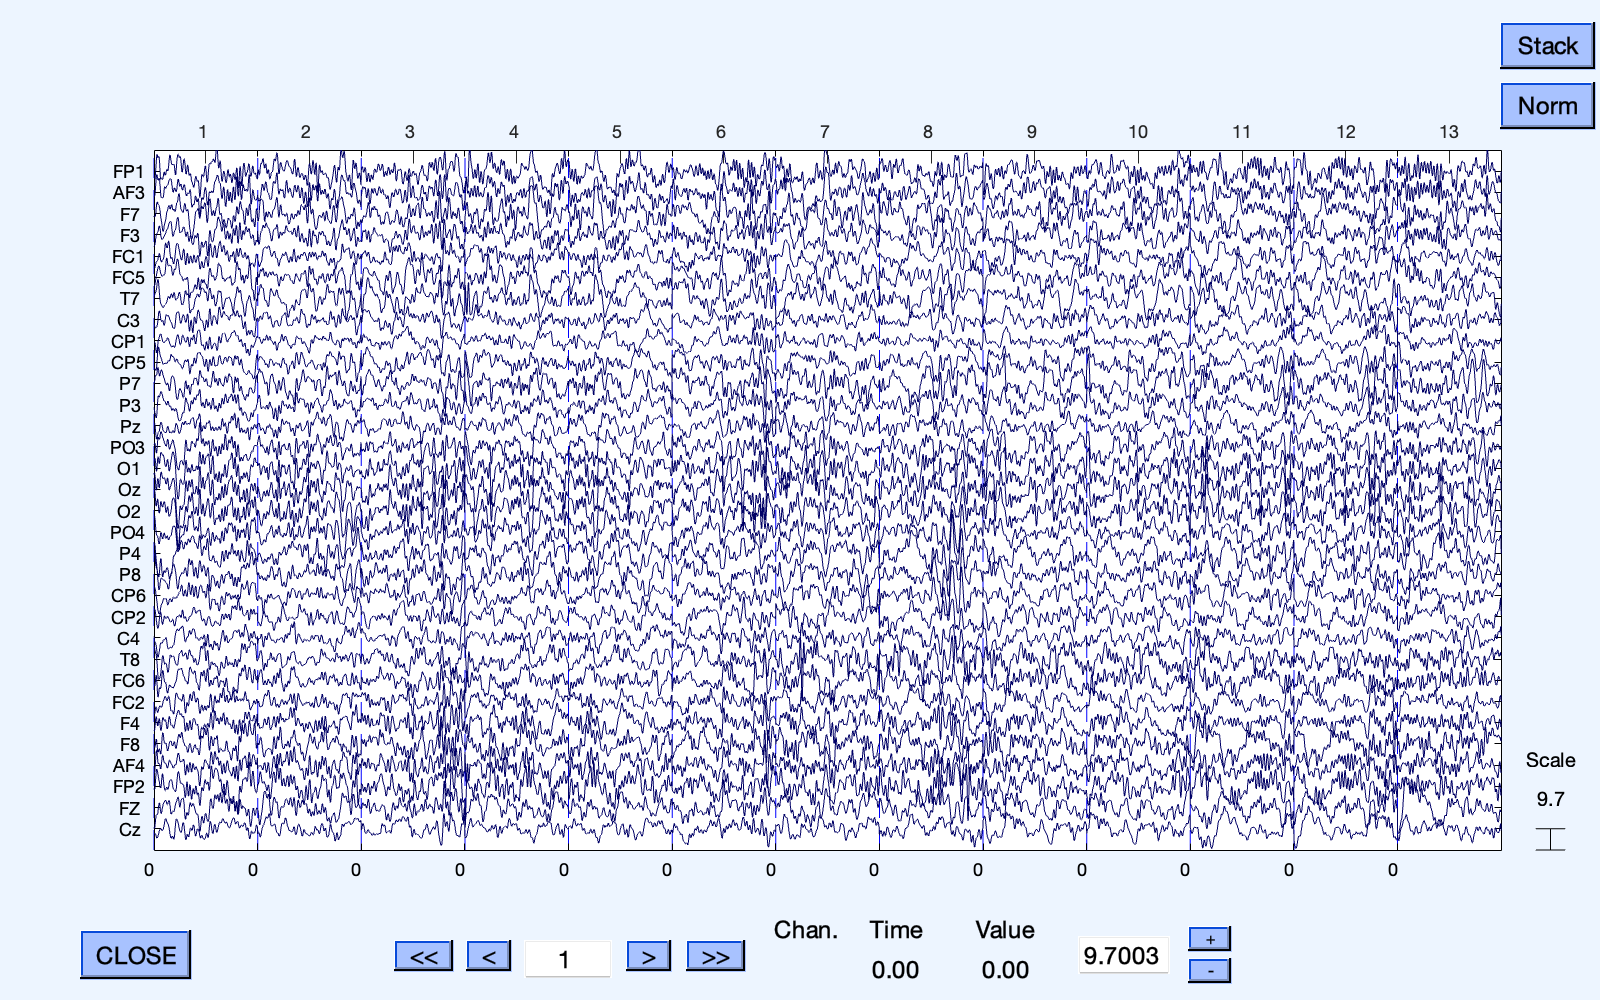


eegplot(epoch_target, 'srate', srate, 'eloc_file', ch_locs, 'title', 'target', 'winlength', 13);

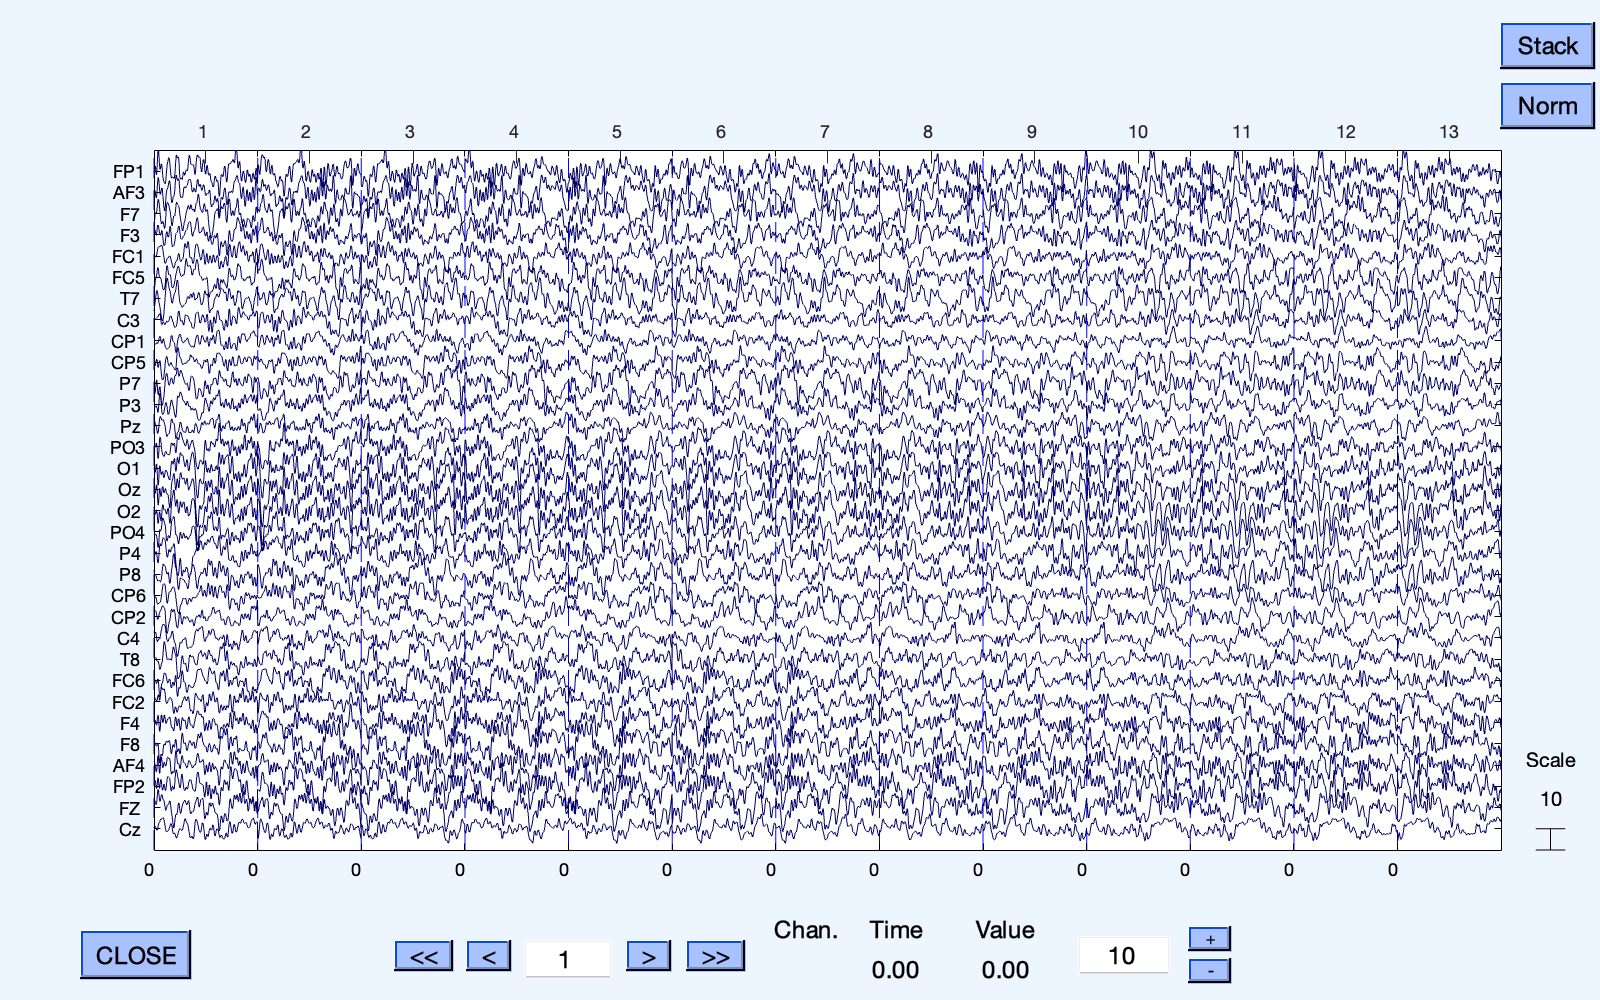

eegplot(epoch_nontarget, 'srate', srate, 'eloc_file', ch_locs, 'title', 'nontarget', 'winlength', 13);

From now on, you can handle data based on windows (epochs). In other words, you can exclude certain window if it contains severe artifacts.

## Run singular value decomposition (SVD) and principal component analysis (PCA)

SVD and PCA are very similar, while SVD takes input as spatiotemporal data [ch x time], whereas PCA takes input as covariance matrices.

### SVD

[U, S, V] = svd(filt_eeg, 'econ');

U =     0.5911    0.3694   -0.1245    0.3925   -0.0504    0.1846   -0.0092    0.0772   -0.3901    0.2044   -0.1466    0.0252    0.0923   -0.2007    0.0488    0.0138   -0.0491   -0.0127   -0.0007   -0.0029   -0.0122    0.0148    0.0055    0.0038    0.0009    0.0050    0.0065    0.0053   -0.0098   -0.0057   -0.0005   -0.1768
    0.2310   -0.0046    0.2504   -0.1180    0.1953   -0.0998   -0.3468   -0.0822    0.0882    0.2109    0.0540    0.4925   -0.2871    0.2700    0.2987   -0.0148   -0.0109    0.2735   -0.1916    0.0109    0.0055   -0.0875    0.0363    0.0039    0.0082   -0.0075   -0.0045   -0.0051    0.0093   -0.0086   -0.0047   -0.1768
    0.1522    0.4509    0.0048    0.0652   -0.4876   -0.0873   -0.0703   -0.1905    0.2945   -0.4396    0.1559   -0.0710   -0.2543    0.2283   -0.1273    0.0444    0.0707   -0.0249    0.0208    0.0025   -0.0152    0.0200   -0.0157   -0.0007   -0.0057   -0.0026    0.0000   -0.0052    0.0009    0.0086    0.0029   -0.1768
    0.0641   -0.0061    0.3019   

S = 1.0e+04 *

    1.3344         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.5615         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.4626         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0  

V =    -0.0001    0.0006    0.0010    0.0005   -0.0006    0.0002   -0.0009    0.0020   -0.0002    0.0009    0.0011    0.0007   -0.0019   -0.0003   -0.0006    0.0002    0.0019    0.0006   -0.0006   -0.0012   -0.0002   -0.0002    0.0026   -0.0013   -0.0002   -0.0014   -0.0006    0.0001    0.0003   -0.0015   -0.0019   -0.0014
   -0.0008    0.0019    0.0005    0.0012    0.0017   -0.0007    0.0004    0.0002   -0.0001    0.0009    0.0016    0.0006   -0.0021   -0.0002    0.0005   -0.0023    0.0009   -0.0010   -0.0013   -0.0029   -0.0013    0.0006    0.0037   -0.0006    0.0014   -0.0009   -0.0017    0.0010    0.0020   -0.0010   -0.0020   -0.0014
   -0.0014    0.0032    0.0000    0.0018    0.0037   -0.0016    0.0016   -0.0014   -0.0001    0.0010    0.0021    0.0005   -0.0023   -0.0001    0.0015   -0.0045    0.0001   -0.0025   -0.0019   -0.0044   -0.0022    0.0013    0.0047    0.0000    0.0029   -0.0005   -0.0028    0.0019    0.0037   -0.0006   -0.0021   -0.0014
   -0.0019    0.0042   -0.0003   

 % X = U * S * V'

### PCA

C = cov(filt_eeg');
[Vpca, D] = eig(C);
[~, idx] = sort(diag(D), 'descend');
Vpca = Vpca(:, idx);
D = D(idx, idx);

, which is same as

[W, Y] = pca(filt_eeg);

### Let's draw principal component of EEG data

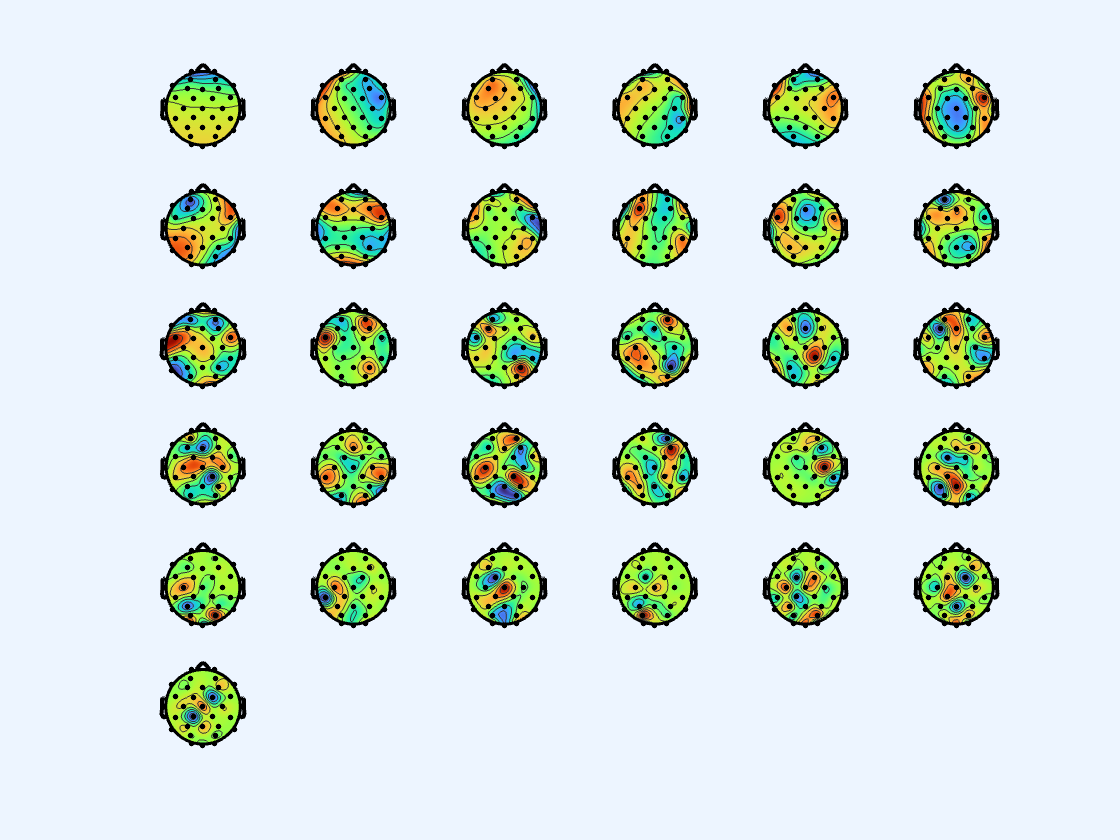

figure,
for i=1:size(filt_eeg, 1)-1
    subplot(6,6,i);
    topoplot(W(i, :), ch_locs);
end

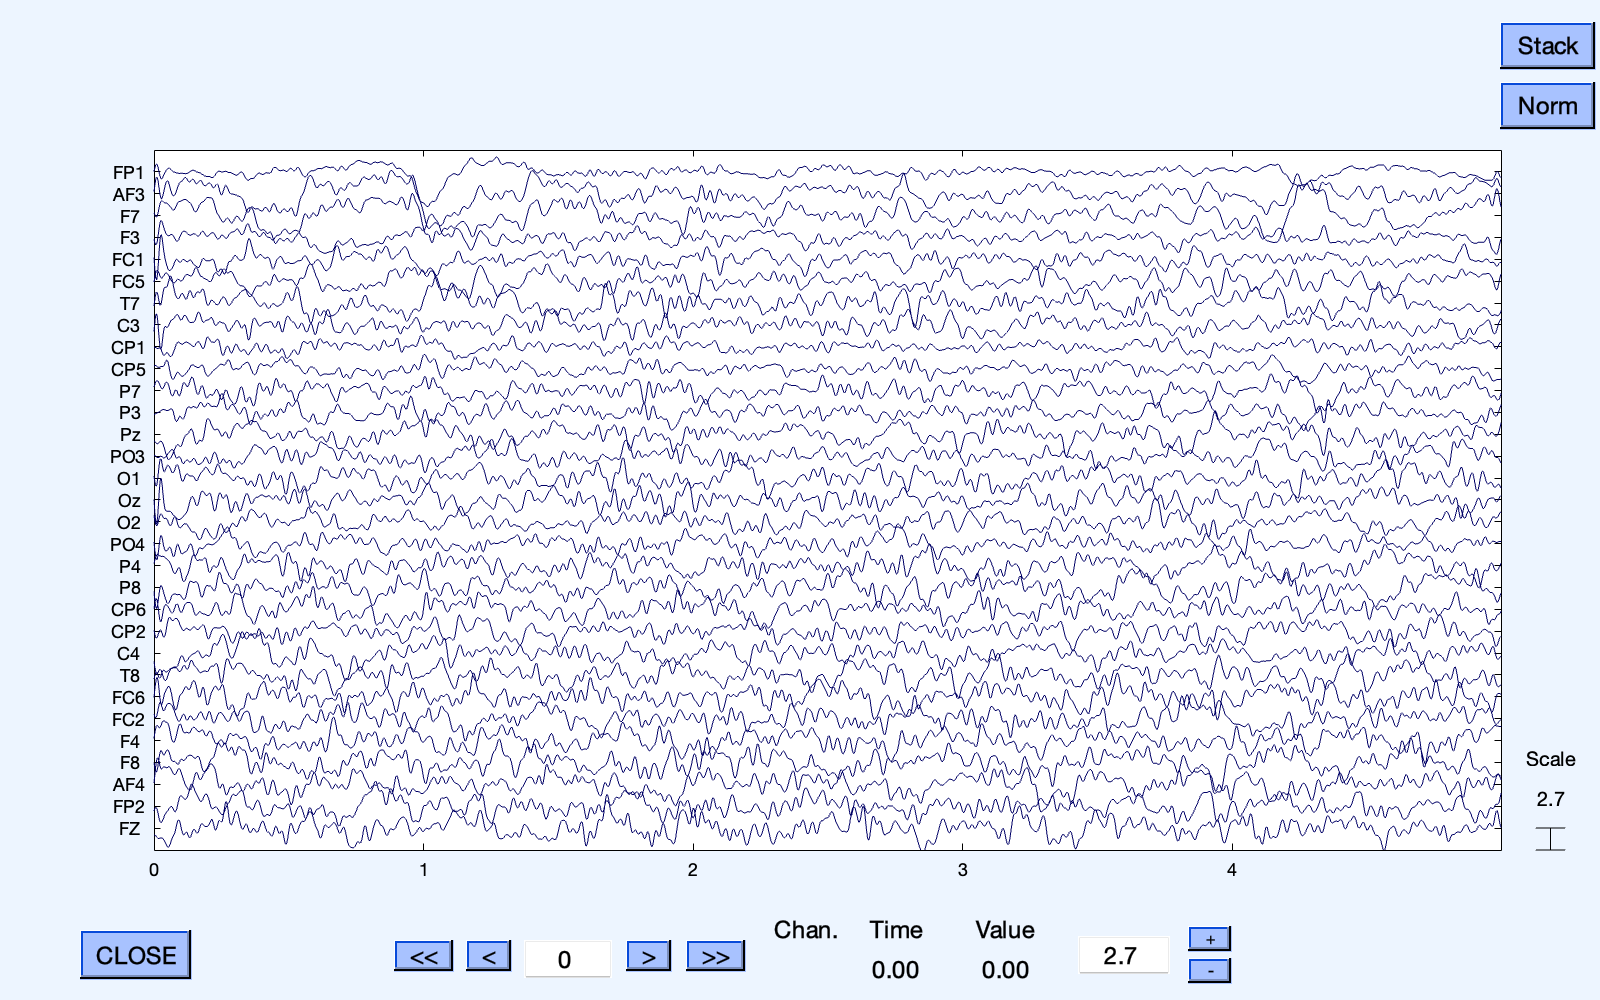

eegplot(Y, 'srate', srate, 'eloc_file', ch_locs);

You can check their spatial and temporal properties, with this information, you can choose signal space and noise space with proper threshold.

## Selecting a few components

k = 5;
X_reduced = U(:,1:k) * S(1:k,1:k) * V(:,1:k)';

X_reduced is reconstructed by 5 components, let's compare it to the original data

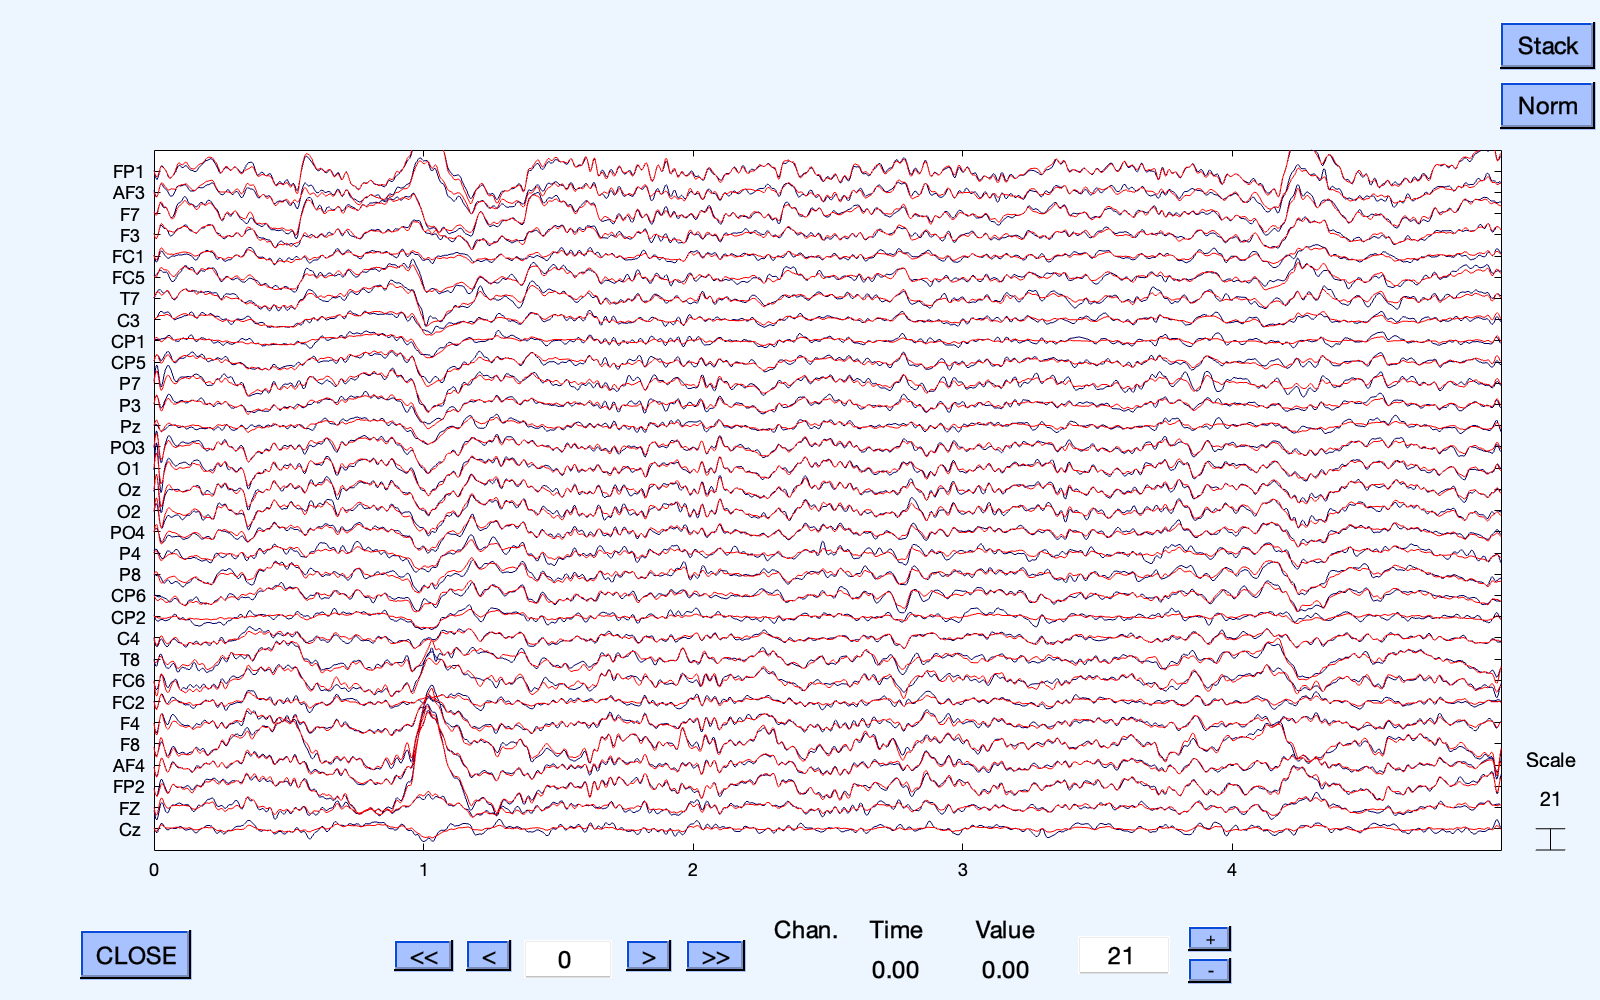

eegplot(filt_eeg, 'srate', srate, 'eloc_file', ch_locs, 'data2', X_reduced);

They looks similar, indicating 5 strong components could explain current periods.

## Independent Component Analysis (ICA)

Here, we will apply ICA to reduce physiological artifacts, such as eye blinking and eye movements. 